# Scientific Programming, Worksheet 4, Ex. 4

*Written by: Kundyz Muktar, Course: Scientific Programming (2025), MATLAB version: R2023a*

## Part B

Validate 2D Gauss quadrature for f(x,y)=exp(-(x^2+y^2)) on [0,1] x [0,2]

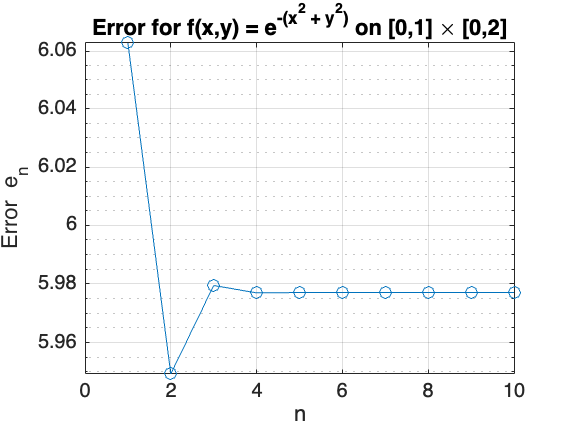

clear; clc; close all;

Qref = 6.63579699762125149;
f = @(x,y) exp(-(x.^2 + y.^2));
a = 0; b = 1; c = 0; d = 2;  

n_values = 1:10;
errors  = zeros(size(n_values));
for idx = 1:length(n_values)
    n = n_values(idx);

    [x, wx] = quadratureGauss(a, b, n);
    [y, wy] = quadratureGauss(c, d, n);

    Qapprox = 0;
    for i = 1:n
        for j = 1:n
            Qapprox = Qapprox + wx(i)*wy(j)*f(x(i), y(j));
        end
    end

    errors(idx) = abs(Qref - Qapprox);
end


figure;
semilogy(n_values, errors, 'o-');
grid on;
xlabel('n');
ylabel('Error  e_n');
title('Error for f(x,y) = e^{-(x^2 + y^2)} on [0,1] \times [0,2]');

Choose n in N with 2n - 1 > max(j,k).

## Part A

j = 2;
k = 3;

n = 4; 

f = @(x,y) x.^j .* y.^k;

% gauss in x and y (both from [0,1])
[x, wx] = quadratureGauss(0, 1, n);
[y, wy] = quadratureGauss(0, 1, n);

% 2d gauss quad sum
Qapprox = 0;
for i = 1:n
    for l = 1:n
        Qapprox = Qapprox + wx(i) * wy(l) * f(x(i), y(l));
    end
end

Qexact = 1/((j+1)*(k+1));

fprintf('j=%d, k=%d, n=%d,  Qapprox=%.8f,  Qexact=%.8f,  Error=%.2e\n', ...
        j, k, n, Qapprox, Qexact, abs(Qapprox - Qexact));

j=2, k=3, n=4,  Qapprox=0.08333333,  Qexact=0.08333333,  Error=1.17e-13


***Taken from Worksheet 4, Ex 3***

We first call your 1D quadrature function **quadrature(a, b, nx) **to get the nodes **x_i **and weights **w_i **for the interval **[a, b].**

We do the same for [**c, d]** to get **y_j** and **w_j. **

function Q = tensorQuadrature(a, b, c, d, f, nx, ny)

    [x, wX] = quadrature(a, b, nx); % x direction
    [y, wY] = quadrature(c, d, ny); % y direction
 
    Q = 0;
    for i = 1:nx
        for j = 1:ny
            Q = Q + wX(i) * wY(j) * f(x(i), y(j));
        end
    end
end


***Taken from Worksheet 3, Ex 3:***

function [x, w] = quadrature(a, b, n)
    if n == 1
        x = a;  % if only one node, choose the left endpoint (could also choose the midpoint)
        w = (b-a);
        return
    end

    h = (b - a) / (n - 1);  % quadrature step size
    x = a:h:b;
    

    x01 = linspace(0, 1, n); 
    w01 = quadratureWeights(x01);
    w = (b - a) * w01;
end

%% from ex 1 or 2
function w = quadratureWeights(x)
    n = numel(x);
    A = zeros(n,n);
    b = zeros(n,1);

    for row = 0:n-1
        A(row+1,:) = x.^row;
        b(row+1)   = 1/(row+1);
    end

    w = A\b;
end
%% from ex 1
function [A, b_vals] = build_A_b(k, N, x_vals)
    % Here k is the maximum polynomial degree (so there are k+1 moments)
    A = zeros(k+1, N);
    b_vals = zeros(k+1, 1);
    for row = 0:k
        A(row+1, :) = x_vals.^row;
        b_vals(row+1) = 1/(row+1);
    end
end



***Taken from Worksheet 3, Ex 5***

function [x, w] = quadratureGauss(a, b, n)

    [x01, w01] = gaussLegendre(n);
    x = ((b - a)/2) * x01 + (a + b)/2;
    w = ((b - a)/2) * w01;

end


%% Gauss Legendre Quadrature Weights
% calculate weights and nodes of Gauss Legendre quadrature on [-1,1] with n nodes
% code 'borrowed' from "numerical recipes" (originally in C)
function [x, w] = gaussLegendre(n)
    % Gauss–Legendre Quadrature on [-1,1] with n nodes
    x = zeros(n,1);
    w = zeros(n,1);

    % The roots of the Legendre polynomial P_n are symmetrical in [-1,1].
    % We'll find the roots in [0,1] and mirror them.
    for i = 1:(n+1)/2
        % First approximation for i-th root
        z = cos(pi*(i - 0.25)/(n + 0.5));

        % Newton iteration
        zOld = inf;
        while abs(z - zOld) > 1e-12
            p1 = 1;   % P_0(z)
            p2 = 0;   % P_{-1}(z) dummy

            % Recurrence to compute P_n(z)
            for j = 1:n
                p3 = p2;
                p2 = p1;
                p1 = ((2*j - 1)*z*p2 - (j - 1)*p3)/j;  
            end

            % Derivative of P_n(z) using P_{n-1}(z) = p2
            pp = n*(z*p1 - p2)/(z^2 - 1);

            zOld = z;
            z = z - p1/pp;
        end

        % Set root and its symmetric counterpart
        x(i)         = -z;
        x(n + 1 - i) =  z;

        % Calculate weight (same for both symmetrical roots)
        wVal = 2 / ((1 - z^2)*pp^2);
        w(i)            = wVal;
        w(n + 1 - i)    = wVal;
    end

    % Return row vectors if you prefer
    x = x(:).'; 
    w = w(:).';
end